General overview of pole locations in s-Plane

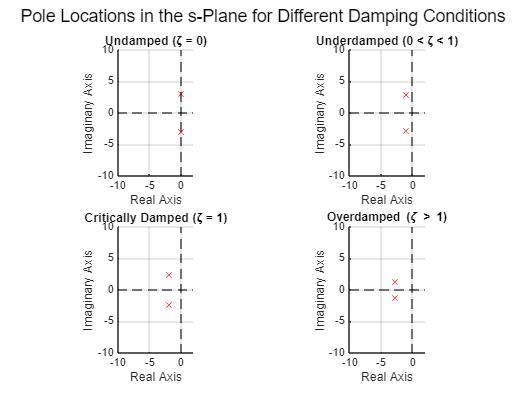

%% Plotting Pole Locations for Different Damping Cases (Separate Graphs)

% Parameters
m = 25/9;                   % mass (kg)
k = 25;                  % spring constant (N/m)
b_values = [0, 5, 10, 15]; % Damping coefficients for various cases

% Natural frequency
omega_n = sqrt(k/m);

% Case labels
labels = {'Undamped (ζ = 0)', ...
          'Underdamped (0 < ζ < 1)', ...
          'Critically Damped (ζ = 1)', ...
          'Overdamped (\zeta > 1)'};

% Create figure
figure;
for i = 1:4
    b = b_values(i);
    zeta = b / (2 * sqrt(k * m));  % Damping ratio
    
    % Compute poles
    a = 1;
    s1 = -zeta * omega_n + omega_n * sqrt(zeta^2 - 1);
    s2 = -zeta * omega_n - omega_n * sqrt(zeta^2 - 1);
    
    % Create subplot
    subplot(2, 2, i);
    hold on; grid on; axis equal;
    xlabel('Real Axis'); ylabel('Imaginary Axis');
    title(labels{i});
    
    % Plot poles
    plot(real(s1), imag(s1), 'rx', 'MarkerFaceColor', 'r');
    plot(real(s2), imag(s2), 'rx', 'MarkerFaceColor', 'r');
    
    % Axis limits
    xlim([-10, 2]);
    ylim([-10, 10]);
    
    % Add origin lines
    xline(0, '--k');
    yline(0, '--k');
end

sgtitle('Pole Locations in the s-Plane for Different Damping Conditions');